load('Encoder_2.mat');
% QEI
pulseX1 = encode2{7};
pulseX2 = encode2{9};
pulseX4 = encode2{3};
thetaX1 = encode2{8};
thetaX2 = encode2{11};
thetaX4 = encode2{5};
wX1 = encode2{6};
wX2 = encode2{10};
wX4 = encode2{4};

% Polling
PX1 = encode2{12}; 
PX2 = encode2{13};
PX4 = encode2{14};

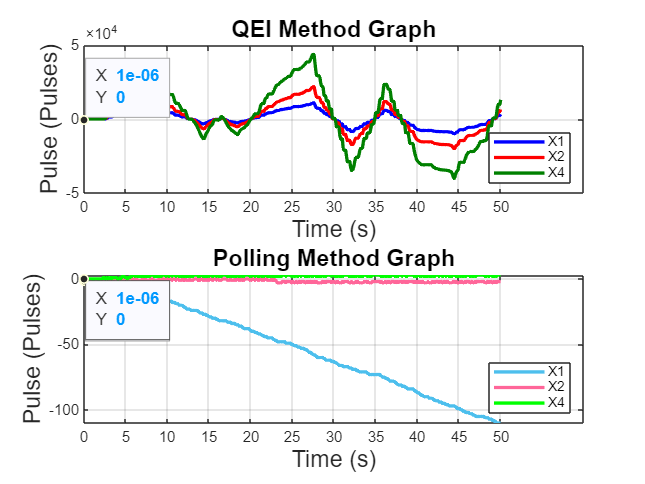

% QEI and Polling in one Frame
figure;
subplot(2, 1, 1); 
quiX1 = plot(pulseX1.Values.Time, pulseX1.Values.Data, 'b-', 'LineWidth', 2);
hold on;
quiX2 = plot(pulseX2.Values.Time, pulseX2.Values.Data, 'r-', 'LineWidth', 2);
quiX4 = plot(pulseX4.Values.Time, pulseX4.Values.Data, 'Color', [0, 0.5, 0], 'LineWidth', 2);
hold off;
% Add on
datatip(quiX1);
datatip(quiX2);
datatip(quiX4);
xticks(0:5:50);
xticklabels(0:5:50);
grid on;
title('QEI Method Graph', 'FontSize', 14);
xlabel('Time (s)', 'FontSize', 14); 
ylabel('Pulse (Pulses)', 'FontSize', 14); 
legend('X1', 'X2', 'X4', 'Location', 'southeast');


subplot(2, 1, 2); 
pollingX1 = plot(PX1.Values.Time, PX1.Values.Data, 'Color', [0.3, 0.75, 0.93], 'LineWidth', 2);
hold on;
pollingX2 = plot(PX2.Values.Time, PX2.Values.Data, 'Color', [1, 0.4, 0.6], 'LineWidth', 2);
pollingX4 = plot(PX4.Values.Time, PX4.Values.Data, 'g-', 'LineWidth', 2);
hold off;
% Add on
datatip(pollingX1);
datatip(pollingX2);
datatip(pollingX4);
xticks(0:5:50);
xticklabels(0:5:50);
grid on;
title('Polling Method Graph', 'FontSize', 14);
xlabel('Time (s)', 'FontSize', 14); 
ylabel('Pulse (Pulses)', 'FontSize', 14); 
legend('X1', 'X2', 'X4', 'Location', 'southeast');

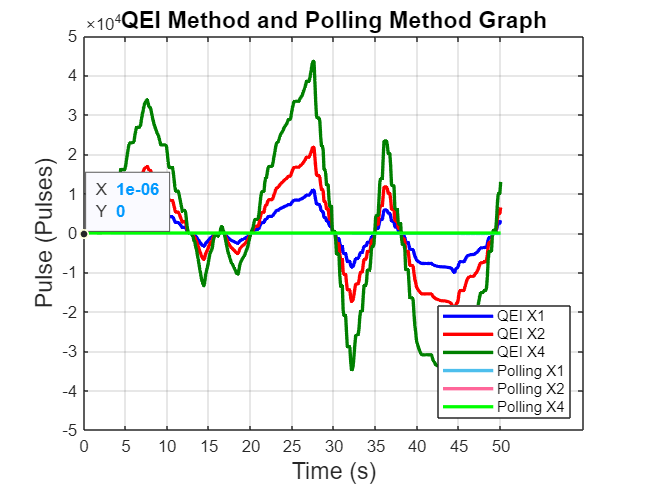

% QEI and Polling
figure;
quiX1 = plot(pulseX1.Values.Time, pulseX1.Values.Data, 'b-', 'LineWidth', 2);
hold on;
quiX2 = plot(pulseX2.Values.Time, pulseX2.Values.Data, 'r-', 'LineWidth', 2);
quiX4 = plot(pulseX4.Values.Time, pulseX4.Values.Data, 'Color', [0, 0.5, 0], 'LineWidth', 2);
pollingX1 = plot(PX1.Values.Time, PX1.Values.Data, 'Color', [0.3, 0.75, 0.93], 'LineWidth', 2);
pollingX2 = plot(PX2.Values.Time, PX2.Values.Data, 'Color', [1, 0.4, 0.6], 'LineWidth', 2);
pollingX4 = plot(PX4.Values.Time, PX4.Values.Data, 'g-', 'LineWidth', 2);
hold off;
% Add on
datatip(quiX1);
datatip(quiX2);
datatip(quiX4);
datatip(pollingX1);
datatip(pollingX2);
datatip(pollingX4);
xticks(0:5:50);
xticklabels(0:5:50);
grid on;
title('QEI Method and Polling Method Graph', 'FontSize', 14);
xlabel('Time (s)', 'FontSize', 14); 
ylabel('Pulse (Pulses)', 'FontSize', 14); 
legend('QEI X1', 'QEI X2', 'QEI X4', 'Polling X1', 'Polling X2', 'Polling X4', 'Location', 'southeast');

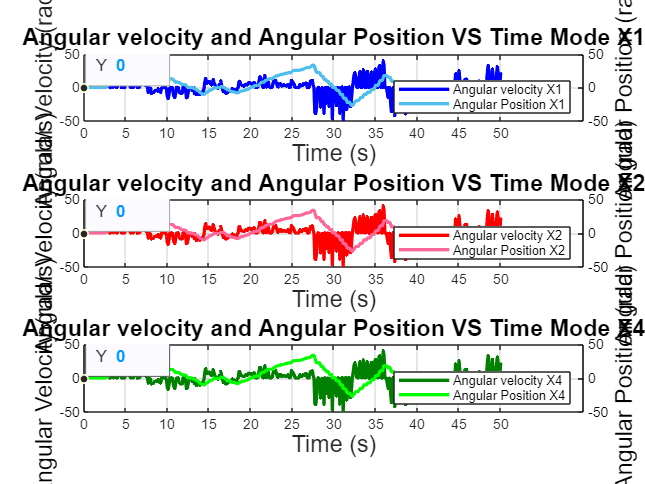

% Angular velocity and Theta VS Time All Mode in one Frame
figure;
subplot(3, 1, 1); 
AngularVelocityX1 = plot(wX1.Values.Time, wX1.Values.Data, 'b-', 'LineWidth', 2);
ylabel('Angular Velocity (rad/s)', 'FontSize', 14); 
yyaxis right
thX1 = plot(thetaX1.Values.Time, thetaX1.Values.Data, 'Color', [0.3, 0.75, 0.93], 'LineWidth', 2);
ylabel('Angular Position (rad)', 'Color', 'k', 'FontSize', 14); 
set(gca, 'YColor', 'k');
% Add on
datatip(AngularVelocityX1);
datatip(thX1);
xticks(0:5:50);
xticklabels(0:5:50);
grid on;
title('Angular velocity and Angular Position VS Time Mode X1', 'FontSize', 14);
xlabel('Time (s)', 'FontSize', 14); 
legend('Angular velocity X1', 'Angular Position X1', 'Location', 'Southeast');


subplot(3, 1, 2); 
yyaxis left
AngularVelocityX2 = plot(wX2.Values.Time, wX2.Values.Data, 'r-', 'LineWidth', 2);
ylabel('Angular Velocity (rad/s)','Color', 'k', 'FontSize', 14);
set(gca, 'YColor', 'k');
yyaxis right
thX2 = plot(thetaX2.Values.Time, thetaX2.Values.Data, 'Color', [1, 0.4, 0.6], 'LineWidth', 2);
ylabel('Angular Position (rad)', 'Color', 'k', 'FontSize', 14); 
set(gca, 'YColor', 'k');
% Add on
datatip(AngularVelocityX2);
datatip(thX2);
xticks(0:5:50);
xticklabels(0:5:50);
grid on;
title('Angular velocity and Angular Position VS Time Mode X2', 'FontSize', 14);
xlabel('Time (s)', 'FontSize', 14); 
legend('Angular velocity X2', 'Angular Position X2', 'Location', 'Southeast');


subplot(3, 1, 3); 
yyaxis left
AngularVelocityX4 = plot(wX4.Values.Time, wX4.Values.Data, 'Color', [0, 0.5, 0], 'LineWidth', 2);
ylabel('Angular Velocity (rad/s)','Color', 'k', 'FontSize', 14); 
set(gca, 'YColor', 'k');
yyaxis right
thX4 = plot(thetaX4.Values.Time, thetaX4.Values.Data, '-g', 'LineWidth', 2);
ylabel('Angular Position (rad)', 'Color', 'k', 'FontSize', 14); 
set(gca, 'YColor', 'k');
% Add on
datatip(AngularVelocityX4);
datatip(thX4);
xticks(0:5:50);
xticklabels(0:5:50);
grid on;
title('Angular velocity and Angular Position VS Time Mode X4', 'FontSize', 14);
xlabel('Time (s)', 'FontSize', 14); 
legend('Angular velocity X4', 'Angular Position X4', 'Location', 'Southeast');

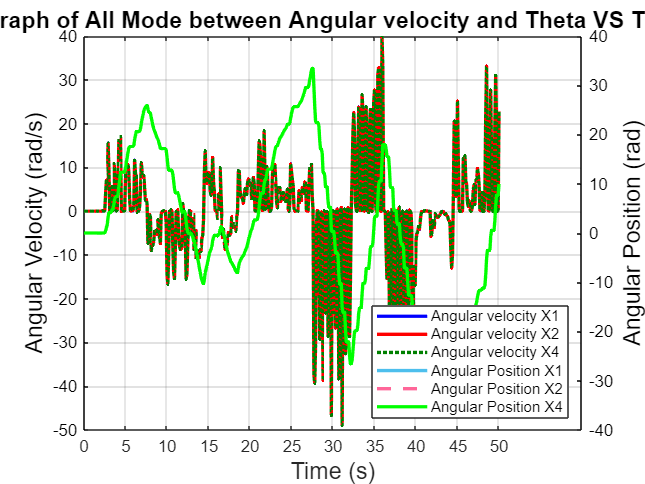

% Angular velocity VS Theta All
figure;
yyaxis left
AngularVelocityX1 = plot(wX1.Values.Time, wX1.Values.Data, 'b-', 'LineWidth', 2);
hold on
AngularVelocityX2 = plot(wX2.Values.Time, wX2.Values.Data, 'r-', 'LineWidth', 2);
AngularVelocityX4 = plot(wX4.Values.Time, wX4.Values.Data, 'Color', [0, 0.5, 0], 'LineWidth', 2);
ylabel('Angular Velocity (rad/s)','Color', 'k', 'FontSize', 14); 
set(gca, 'YColor', 'k');
yyaxis right
thX1 = plot(thetaX1.Values.Time, thetaX1.Values.Data, 'Color', [0.3, 0.75, 0.93], 'LineWidth', 2);
thX2 = plot(thetaX2.Values.Time, thetaX2.Values.Data, 'Color', [1, 0.4, 0.6], 'LineWidth', 2);
thX4 = plot(thetaX4.Values.Time, thetaX4.Values.Data, 'g-', 'LineWidth', 2);
ylabel('Angular Position (rad)', 'Color', 'k', 'FontSize', 14); 
set(gca, 'YColor', 'k');
hold off
% Add on
xticks(0:5:50);
xticklabels(0:5:50);
grid on;
title('Graph of All Mode between Angular velocity and Theta VS Time', 'FontSize', 14);
xlabel('Time (s)', 'FontSize', 14); 
legend('Angular velocity X1', 'Angular velocity X2', 'Angular velocity X4', 'Angular Position X1', 'Angular Position X2', 'Angular Position X4', 'Location', 'Southeast');